x = linspace(0,20,3)
y = f(x);
p = polyfit(x,y,2);
est = polyval(p,xtest);

Et(true,est)

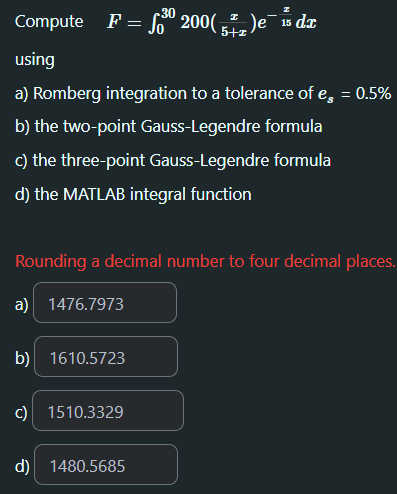

f = @(x) 200.*(x ./ (5+x) ).*exp(-(x/15));

a = 0;
b = 30;

[I_romberg, ea, iter] = romberg(f,a,b,0.5);
I_romberg = round(I_romberg,4);
fprintf("romberg = %.4f",I_romberg)

romberg = 1476.7973

Gauss-Legendre

a1 = (b+a)/2;
a2 = (b-a)/2;

f2 = @(xd) (f(a1+a2*xd))*a2;

I_2point = round(f2(-1/sqrt(3)) + f2(1/sqrt(3)),4);
fprintf("I_2point = %.4f",I_2point);

I_2point = 1610.5723

I_3point = round( 5/9 * f2(-sqrt(3/5)) + 8/9 * f2(0.0) + 5/9 * f2(sqrt(3/5)) ,4 );
fprintf("I_3point = %.4f",I_3point);

I_3point = 1510.3329

Integral

I_integral = round( integral(f,a,b),4 );
fprintf("I_integral = %.4f",I_integral)

I_integral = 1480.5685